**Reset all:**

clc;
close all;
clear;

%To run the script, please open the HMI file first. This will open the GUI.

%Declare fixed variables
Tb = 288.2;             %K          
Lb = 0.0065;            %K/m
Pb = 101.325;           %
hb = 0;
g = 9.80665;
Mol = 0.0289644;
R1 = 8.3144598;
R = 287.5;

%Variables to be changed
T0 = 0;        %K
P0 = 0;        %
T1 = 0;
P1 = 0

P1 = 0

W1 = 0;
T2 = 0;
P2 = 0

P2 = 0

W2 = 0;
T21 = 0;
P21 = 0;
W21 = 0;
T3 = 0;
P3 = 0;
W3 = 0;
T31 = 0;
P31 = 0;
W31 = 0;
P4 = 0;
Q = 0;
W4 = 0;
WHPC = 0;
T41 = 0;
P41 = 0;
W41 = 0;
WLPC = 0;
T415 = 0;
P415 = 0;
W415 = 0;
T5 = 0;
P5 = 0;
W5 = 0;
Ps = 0;
Ts = 0;
Vj = 0;
rho = 0;
An = 0;
Fn = 0;
SFC = 0;
ETATH = 0;

%Run the Simulink model (HMI)
sim('./HMI_V3.slx');

%Request the input variables
engine_Type = ans.typeOfEngine;         % 0=Single spool | 1=Double spool
turbo_Fan = ans.turboFan;               % 0=Yes | 1=No
bleed = ans.bleed;                      % 0=Yes | 1=No
poly_Isen = ans.polytropicIsentropic;   % Polytropic=0 | Isentropic=1

Height = ans.height;                            %Height in meters
M = ans.mach;                                   %Mach number
P3Q2_LPC = ans.PressureratioLPC;                %Pressure ratio low pressure compressor
P3Q2_HPC = ans.PressureratioHPC;                %Pressure ratio High pressure compressor
P_loss_Compressor = ans.pressureLossCompressor; %Pressure loss compressor
P_loss_Combuster = ans.pressureLossCombuster;   %Pressure loss combuster
W0 = ans.massFlow;                              %Mass flow ambient
LHV = ans.fuelCalorificValue;                   %fuelCalorificValue
y_t = ans.gammaTurbine;                         %Heat capacity(Gamma) ratio turbine
y_c = ans.gammaCompressor;                      %Heat capacity(Gamma) ratio compressor
Cp_hot = ans.CPTurbine;                         %Specific(CP) heat turbine
Cp_cold = ans.CPCompressor;                     %Specific(CP) heat compressor

ETHA_Comp = ans.Isentropiccompressor;           %Isentropic efficiency compressor
ETHA_Comb = ans.Isentropiccombuster;            %Isentropic efficiency combuster
ETHA_turb = ans.Isentropicturbine;              %Isentropic efficiency turbine
ETHA_Comp_Poly = ans.Polytropiccompressor;
ETHA_Comb_Poly = ans.Polytropiccombuster;
ETHA_turb_Poly = ans.Polytropicturbine;
T41 = ans.Temperaturecombustion;                 %Temperature after combustion
Bleed1 = 0.01;                                  % Bleed air from compressor to outlet     (%)
Bleed2 = 0.08;                                  % Bleed air from compressor to LPT        (%)
Bleed3 = 0.075;                                 % Bleed air from compressor to HPT        (%)
Bleed4 = 0.047;                                 % Bleed air to first LPT nozzle           (%)
Bleed5 = 0.033;                                 % Bleed air to second LPT nozzle          (%)
JetpipeP_loss = 0;
IntakeP_loss = 0;
CP_turbine = 1.150;
CP_compressor = 1.005;
CompressorP_loss = 0.005;

**Station 0: Atmospheric**

P0 = Pb * ((Tb - (Height - hb) * Lb)/Tb).^((g * Mol)/(R1 * Lb));    %Pressure Ambient
T0 = Tb - (Height * Lb);                                            %Temperature Ambient                                                            %Massflow Ambient

Functions

if poly_Isen == 0
    ETHA_Comb = (P3Q2_LPC^((y_c-1)/y_c)-1)/(P3Q2_LPC^((y_c-1)/(y_c*ETHA_Comp_Poly))-1);
    ETHA_Comp = (P3Q2_LPC^((y_c-1)/y_c)-1)/(P3Q2_LPC^((y_c-1)/(y_c*ETHA_Comb_Poly))-1);
    ETHA_Turb = (P3Q2_LPC^((y_t-1)/y_t)-1)/(P3Q2_LPC^((y_t-1)/(y_t*ETHA_turb_Poly))-1);
end
[T1, P1, W1] = Inlet(T0, P0, W0);
[T2, P2, W2] = LPC_Inlet(T1, P1, W1, IntakeP_loss);
if engine_Type == 0
    [P3, T3, W3] = HPC_single(P2, T2, W2, P3Q2_HPC, y_c, ETHA_Comp, Bleed1, W0, CompressorP_loss);
else
    [P21, T21, W21] = LPC(T2, P2, W2, P3Q2_LPC, y_c, ETHA_Comp);
    [P3, T3, W3] = HPC(P21, T21, W21, P3Q2_HPC, y_c, ETHA_Comp, Bleed1, W0, CompressorP_loss);
end
[P31, T31, W31] = Combuster_Inlet(P3, T3, W3, P_loss_Combuster, Bleed2, Bleed3, W0);
[P4, T41, W41, WF, FAR] = Combuster_Outlet(P31, T31, W31, ETHA_Comb, Bleed3, P_loss_Combuster, W0);
if engine_Type == 0
    [T4, P41, W4] = HPT_Inlet(P4, T41, W41, CP_turbine, Bleed3, CP_compressor, T3, W0, W31, WF);
    [T5, P5, W5, WC, Expansion_ratio] = LPT_Outlet_single(T41, P41, W41, W3, CP_compressor, T31, T2, CP_turbine, Bleed1, Bleed5, ETHA_turb, W4, W0)
else
    [T4, P41, W4] = HPT_Inlet(P4, T41, W41, CP_turbine, Bleed3, CP_compressor, T3, W0, W31, WF);
    [T415, P415, W415] = LPT_Inlet(T41, W41, P41, Cp_cold, T21, T0, Cp_hot, ETHA_turb, y_t, W2, W4);
    [T5, P5, W5, WC, Expansion_ratio] = LPT_Outlet(T415, P415, W415, W3, CP_compressor, T31, T2, CP_turbine, Bleed1, Bleed5, ETHA_turb, W4, W0)
end

T5 = 1.3921e+03

P5 = 245.8024

W5 = 97.8956

WC = 2.0585e+04

Expansion_ratio = 1.9418

[T6, P6, W6] = Afterburner_calc(T5, P5, W5, W0, Bleed1, Bleed5)

T6 = 1.3921e+03

P6 = 245.8024

W6 = 102.1956

[T7, P7, W7] = Propelling_nozzle_inlet(T6, P6, W6, JetpipeP_loss)

T7 = 1.3921e+03

P7 = 245.8024

W7 = 102.1956

[T8, P8, W8, Ps, Ts, VN, rho, ANeffective] = Propelling_nozzle_throat(T6, P6, W6, y_c, y_t, R, W0)

T8 = 1.3921e+03

P8 = 245.8024

W8 = 102.1956

Ps = 129.8529

Ts = 1.1601e+03

VN = 666.8542

rho = 0.3893

ANeffective = 0.3852

[T9, P9, W9] = Exhaust_calculations(T8, P8, W8, Ps)

T9 = 1.3921e+03

P9 = 3.1918e+04

W9 = 102.1956

[Vj, Fn, SFC, ETATH, SFN, SPW] = finalCalc(W0, WF, P0, LHV, y_c, R, An, Ps, Ts)

Vj = 683.3222

Fn = 7.0447e+04

SFC = 43.9415

ETATH = 19.0528

SFN = 704.4750

SPW = 704.4750

%[s1, s2, s3] = plot(h, SFC, Fn, ETATH)

%Send the output values 
sim('./HMI_V3.slx');

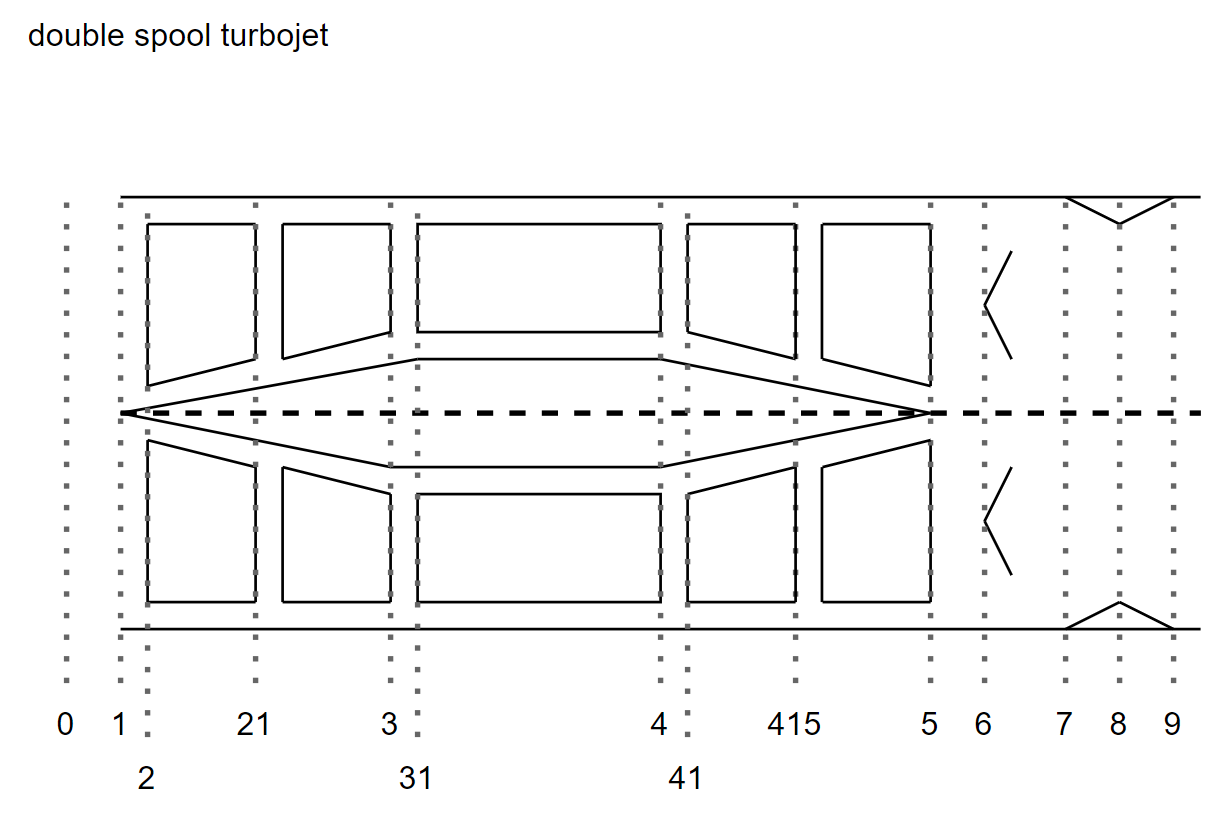

**Station 1: Inlet**

function [T1, P1, W1] = Inlet(T0, P0, W0)
    T1 = T0;
    P1 = P0;
    W1 = W0;
end

**Station 2: LPC (low pressure compressor) inlet**

function [T2, P2, W2] = LPC_Inlet(T1, P1, W1, IntakeP_loss)
    T2 = T1;
    P2 = P1 * (1 - IntakeP_loss); 
    W2 = W1;                            % Nothing is added to the flow
end

**Station 21: LPC**

function [P21, T21, W21] = LPC(T2, P2, W2, P3Q2_LPC, y_c, ETHA_Comp)
    P21 = P2 * P3Q2_LPC;
    T21 = T2 * (1 + ((P21/P2)^((y_c - 1)/y_c)- 1)/ETHA_Comp);
    W21 = W2;                           % Nothing is added to the flow
end

**Station 3: HPC (high pressure compressor) outlet**

function [P3, T3, W3] = HPC(P21, T21, W21, P3Q2_HPC, y_c, ETHA_Comp, Bleed1, W0, CompressorP_loss)
    P3 = P21 * P3Q2_HPC;
    T3 = (T21/ETHA_Comp) * (P3Q2_HPC^((y_c-1)/y_c)-1) + T21;
    W3 = W21 - (W0 * Bleed1) - (W0 * CompressorP_loss);                           % Nothing is added to the flow
end
function [P3, T3, W3] = HPC_single(P2, T2, W2, P3Q2_HPC, y_c, ETHA_Comp, Bleed1, W0, CompressorP_loss)
    P3 = P2 * P3Q2_HPC;
    T3 = (T2/ETHA_Comp) * (P3Q2_HPC^((y_c-1)/y_c)-1) + T2;
    W3 = W2 - (W0 * Bleed1) - (W0 * CompressorP_loss);                           % Nothing is added to the flow
end

**Station 31 Combuster inlet**

function [P31, T31, W31] = Combuster_Inlet(P3, T3, W3, P_loss_Combuster, Bleed2, Bleed3, W0)
    T31 = T3;
    P31 = P3 * (1- P_loss_Combuster);
    W31 = W3 - (W0 * Bleed2) - (W0 * Bleed3);
end

**Station 4: Combustor outlet**

function [P4, T41, W41, WF, FAR] = Combuster_Outlet(P31, T31, W31, ETHA_Comb, Bleed3, P_loss_Combuster, W0)
    P4 = P31 * (1 - P_loss_Combuster);
    T41 = 1600;
    FAR1 = 0.10118 + 2.00376E-05 * (700 - T31);
    FAR2 = 3.7078E-03 - 5.2368E-06 * (700 - T31) - 5.2632E-06 * T41;
    FAR3 = 8.889E-08 * abs(T41 - 950);
    FAR = (FAR1 - sqrt(FAR1.^2 + FAR2) - FAR3)/ETHA_Comb;
    WF = FAR * (W31 + W0 * Bleed3); 
    W41 = W31 + (W0 * Bleed3) + WF;
end

**Station 41: HPT (high pressure turbine) inlet**

function [T4, P41, W4] = HPT_Inlet(P4, T41, W41, CP_turbine, Bleed3, CP_compressor, T3, W0, W31, WF)
    T4 = (W41 * CP_turbine * T41)-((Bleed3 * W0) * CP_compressor * T3)/(W41 * CP_turbine);
    P41 = P4;
    W4 = WF + W31;                           % Nothing is added to the flow
end

**Station 415: LPT (low pressure turbine) inlet**

function [T415, P415, W415] = LPT_Inlet(T41, W41, P41, Cp_cold, T21, T0, Cp_hot, ETHA_turb, y_t, W2, W4)
    WLPC = W2 * Cp_cold * (T21 - T0);
    T415 = T41 - (WLPC./(W4.* Cp_hot));
    P415 = P41 * (1 - (1-(T415/T41))/ ETHA_turb)^(y_t/(y_t- 1));
    W415 = W41;                           % Nothing is added to the flow
end

**Station 5: LPT outlet **

function [T5, P5, W5, WC, Expansion_ratio] = LPT_Outlet_single(T41, P41, W41, W3, CP_compressor, T31, T2, CP_turbine, Bleed1, Bleed5, ETHA_turb, W4, W0)
    WC = W3 * CP_compressor * (T31 - T2);
    T5 = T41 - (WC/(W4 * CP_turbine));
    Expansion_ratio = nthroot((1-(T41-T5)/(ETHA_turb*T41)),(-1/4));
    P5 = P41/Expansion_ratio;
    W5 = W41 + (Bleed5 * W0) + (Bleed1 * W0);
end
function [T5, P5, W5, WC, Expansion_ratio] = LPT_Outlet(T415, P415, W415, W3, CP_compressor, T31, T2, CP_turbine, Bleed1, Bleed5, ETHA_turb, W4, W0)
    WC = W3 * CP_compressor * (T31 - T2);
    T5 = T415 - (WC/(W4 * CP_turbine));
    Expansion_ratio = nthroot((1-(T415-T5)/(ETHA_turb*T415)),(-1/4));
    P5 = P415/Expansion_ratio;
    W5 = W415 + (Bleed5 * W0) + (Bleed1 * W0);
end

**Station 6: Afterburner calculations **

function [T6, P6, W6] = Afterburner_calc(T5, P5, W5, W0, Bleed1, Bleed5)
    T6 = T5;
    P6 = P5;
    W6 = W5 + (W0 * Bleed1) + (W0 * Bleed5);
end

**Station 7: Propelling nozzle inlet**

function [T7, P7, W7] = Propelling_nozzle_inlet(T6, P6, W6, JetpipeP_loss)
    T7 = T6;
    P7 = P6 * (1-JetpipeP_loss);
    W7 = W6;
end

**Station 8: Propelling nozzle throat:**

function [T8, P8, W8, Ps, Ts, VN, rho, ANeffective] = Propelling_nozzle_throat(T6, P6, W6, y_c, y_t, R, W0)
    T8 = T6;                                                
    P8 = P6;
    W8 = W6;
    
    Ps = P6/(1 + (y_c - 1)/2)^(y_c/(y_c-1));
    Ts = T6/(1 + (y_c - 1)/2);
    VN = sqrt(y_t * R * Ts);                                % Nett velocity                                             
    
    rho = (Ps.*1000)./(Ts.*R);
    ANeffective = W0./(VN.* rho);   
end

**Station 9: Exhaust calculations: **

function [T9, P9, W9] = Exhaust_calculations(T8, P8, W8, Ps)
    T9 = T8;
    P9 = P8.*Ps;
    W9 = W8;
end

**Final Calculations**

function [Vj, Fn, SFC, ETATH, SFN, SPW] = finalCalc(W0, WF, P0, LHV, y_c, R, An, Ps, Ts)
    Vj = sqrt(y_c * R *Ts);
    Fn = (W0 + WF).* Vj + An.* (Ps - P0);
    SFN = Fn/100;                                           % Specific thrust
    SFC = (WF./Fn).* 1000000;
    SPW = Fn/W0;                                            % Specific power 
    ETATH = 100.*(3600./(SFC.*(LHV/10^5)));
end

**Plots**

function [s1, s2, s3] = plot(h, SFC, Fn, ETATH)
    s1 = plot (h, SFC,LineWidth=1.5);
    xlabel('Height');
    ylabel('SFC');
    grid on;
    
    s2 = plot (h, Fn,LineWidth=1.5);
    xlabel('Height');
    ylabel('Thrust')
    grid on;
    
    s3 = plot (h, ETATH,LineWidth=1.5);
    xlabel('Height');
    ylabel('ETATH')
    grid on;
end